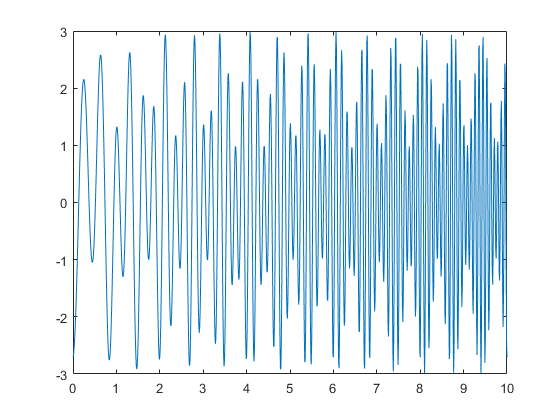

dt = 0.01;
pulse_width = 10;

t = 0 : dt : pulse_width;                       % 0 : 0.01 : 10 [ns]
N_t = length(t);                                % N_t = 1001
df = (1/dt)/N_t;                                % df = 0.1 [GHz]
f = 0 : df : (1/dt)-df;                         % 0 : 0.1 : 100 [GHz]
N_f = length(f);                                % N_f = 1001
noiseAmp = 0;
noiseSD = 1;

%------------------------------------------------------------------------------
    % chirp signal 1 parameter
    chirp1_gain = 1;
    chirp1_mu = 1;
    chirp1_fo = 1;
    chirp1_delta_tau = 0.5;
    
    % chirp signal 2 parameter
    chirp2_gain = 2;
    chirp2_mu = 1;
    chirp2_fo = 3;
    chirp2_delta_tau = 1;
    
st1 = chirp1_gain.*cos(2*pi.*(chirp1_fo*(t - chirp1_delta_tau) + (chirp1_mu/2).*(t - chirp1_delta_tau).^2));
st2 = chirp2_gain.*cos(2*pi.*(chirp2_fo*(t - chirp2_delta_tau) + (chirp2_mu/2).*(t - chirp2_delta_tau).^2));
st = st1 + st2;
plot(t,st)

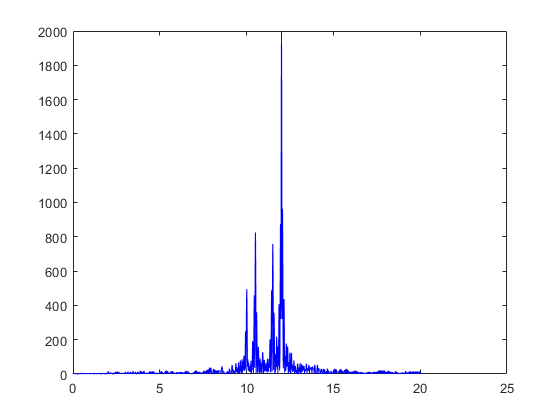


%------------------------------------------------------------------------------

% rt0 = [ zeros(1,N), st1, zeros(1,N), st2, zeros(1,N) ];
% rt = rt0; % + randn(1,length(rt0)); gaussian noise
rt1 = [ zeros(1,N_t), st1, zeros(1,N_t) ];
rt2 = [ zeros(1,N_t+200), st2, zeros(1,N_t-200) ];
           
% rt = rt1 + rt2; 
rt = (rt1 + rt2) + randn(1,length(rt1+rt2))*noiseAmp*noiseSD;    
 
ct1 = length(rt)-N_t;
    for a = 0:ct1
        c(a+1) = rt(a+1:a+N_t)*(st1+st2)';
    end
plot((0:length(c)-1)*dt, abs(c),'b')


%--------------------- 분해능 확인 ------------------------------------------
rt_resolution = c(1:length(t)+1)

rt_resolution =          0    1.9142    3.5852    4.1642    3.3788    1.6468   -0.1635   -1.1903   -1.0108    0.1701    1.6598    2.6563    2.6611    1.7108    0.3206   -0.8148   -1.1928   -0.7483    0.1470    0.9163    1.1028    0.6080   -0.2800   -1.0729   -1.3704   -1.0863   -0.4876   -0.0294   -0.0837   -0.7155   -1.6360   -2.3599   -2.4823   -1.9212   -0.9869   -0.2333   -0.1636   -0.9460   -2.2948   -3.5906   -4.1861   -3.7459   -2.4422   -0.8987    0.1005   -0.0010   -1.2408   -3.0936   -4.7045   -5.2936


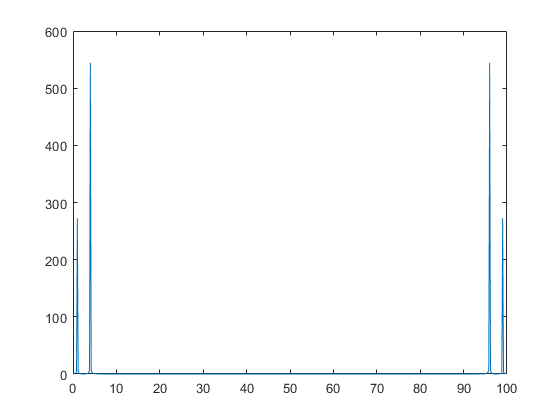

[m,k1] = max(rt_resolution);                         % m = 최댓값, k1 = sample number
c2 = c(1:length(t));          
[n,k2] = max(c2);                                    % n = 최댓값, k2 = sample number
time_diff = (k1-k2)*dt;                             % [ns], dt = 0.01
D_out = (time_diff/2)*3*10^8*10^-9; 

% LPF 통과한 signal st1, st2 --> cos siganl
st_lpf1 = chirp1_gain*cos((2*pi.*chirp1_fo*t*chirp1_delta_tau) + (2*pi.*chirp1_mu*chirp1_delta_tau*t) - (pi.*chirp1_mu*(chirp1_delta_tau)^2));
st_lpf2 = chirp2_gain*cos((2*pi.*chirp2_fo*t*chirp2_delta_tau) + (2*pi.*chirp2_mu*chirp2_delta_tau*t) - (pi.*chirp2_mu*(chirp2_delta_tau)^2));
st_lpf = st_lpf1 + st_lpf2;

yt = st_lpf .* kai';
Yct = fft(yt);
plot(f,abs(Yct))

[m1,h1] = max(abs(Yct))

m1 = 544.2004

h1 = 41


ryct = Yct(1:h1-1)

ryct = 	1.0e+02 *

  -0.0032 + 0.0000i  -0.0033 + 0.0006i  -0.0036 + 0.0013i  -0.0042 + 0.0022i  -0.0052 + 0.0035i  -0.0070 + 0.0054i  -0.0103 + 0.0087i  -0.0168 + 0.0150i  -0.0228 + 0.0207i  -0.8243 + 0.7782i   1.9853 - 1.8651i  -0.8609 + 0.8028i  -0.0205 + 0.0184i  -0.0171 + 0.0152i  -0.0105 + 0.0092i  -0.0070 + 0.0060i  -0.0050 + 0.0042i  -0.0037 + 0.0031i  -0.0028 + 0.0024i  -0.0022 + 0.0019i  -0.0017 + 0.0015i  -0.0013 + 0.0012i  -0.0009 + 0.0011i  -0.0006 + 0.0009i  -0.0003 + 0.0008i   0.0000 + 0.0007i   0.0004 + 0.0007i   0.0007 + 0.0006i   0.0012 + 0.0006i   0.0018 + 0.0006i   0.0025 + 0.0006i   0.0034 + 0.0007i   0.0048 + 0.0008i   0.0068 + 0.0010i   0.0098 + 0.0013i   0.0148 + 0.0019i   0.0240 + 0.0030i   0.0424 + 0.0052i   0.0681 + 0.0084i   2.1218 + 0.2612i


[m2,h2] = max(abs(ryct))

m2 = 272.3979

h2 = 11


%-------------------------------------------------------------------------------

% st에 카이저 윈도우 -> FFT
kai = kaiser(N_t,5);
yt = (st) .* kai';
Yct = fft(yt);
plot(t,abs(Yct))

% correlation에 카이저윈도우 --> FFT
kai1 = kaiser(length(c),5);
yt1 = (c) .* kai1';
Yct1 = fft(yt1);
plot((0:length(c)-1)*dt,abs(Yct1))

%----------------------------------------------------------------
% cos signal ??
st01 = cos((2*pi.*chirp1_fo*t*chirp1_delta_tau) + (2*pi.*chirp1_mu*chirp1_delta_tau*t) - (pi.*chirp1_mu*(chirp1_delta_tau)^2));
st02 = cos((2*pi.*chirp2_fo*t*chirp2_delta_tau) + (2*pi.*chirp2_mu*chirp2_delta_tau*t) - (pi.*chirp2_mu*(chirp2_delta_tau)^2));
st03 = cos((2*pi.*1*t*1.2) + (2*pi.*1*1.2) - (pi.*1*(1.2)^2));
plot(t,st01)
plot(t,st02)
plot(t,st03)
plot(t,st01+st02+st03)
qt = (st01+st02+st03) .* kai';
Yqt = fft(qt);
plot(t,abs(Yqt))

st04 = cos(2*pi.*chirp1_delta_tau*chirp1_mu*t + chirp1_delta_tau*(2*pi.*chirp1_fo - pi.*chirp1_delta_tau*chirp1_mu));
plot(t,st04)


## test

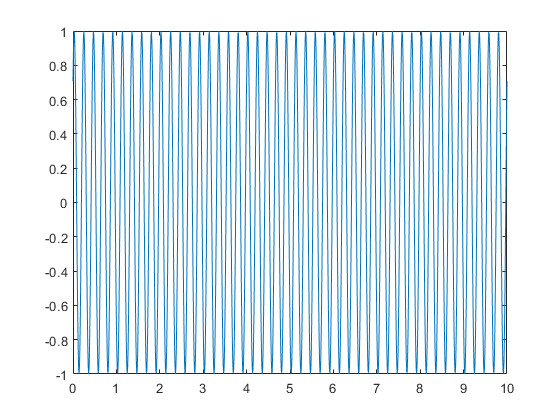

f0 = 2;
delta_tau = 1.5;
mu = 1;
x = cos(2*pi.*f0*t*delta_tau + 2*pi.*mu*delta_tau*t - pi.*mu*(delta_tau)^2);
plot(t,x)